%Experiment 1: Diode-Connected Transitor Characteristics
clear
clf
load('Experiment 1/IinVout/Vout.mat')
load('Experiment 1/IinVout/Iin.mat')
semilogy(Vout, Iin, '.')
hold on
title("Experiment 1: Diode-Connected Transitor Characteristics")
xlabel("Voltage (V)")
ylabel("Current (A")
grid on
%plot(Iin,Vout,".")

%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vout, log(Iin), 5e-4);
Is = exp(bmax)

Is = 4.2539e-15

Ut = 1/mmax

Ut = 0.0258


th_Vout = Ut*log((Iin)/Is);
%plot(Iin, th_Vout)
semilogy(th_Vout, Iin)


%Vin Iout
load('Experiment 1/VinIout/Vin.mat')
load('Experiment 1/VinIout/Iout.mat')
%plot(Vin, Iout,".")
semilogy(Vin, Iout, '.')

%line of best fit
[first2, last2, mmax2, bmax2, Nmax2]=linefit(Vin, log(Iout), 5e-4);
Is2 = exp(bmax2)

Is2 = 4.7192e-15

Ut2 = 1/mmax2

Ut2 = 0.0261

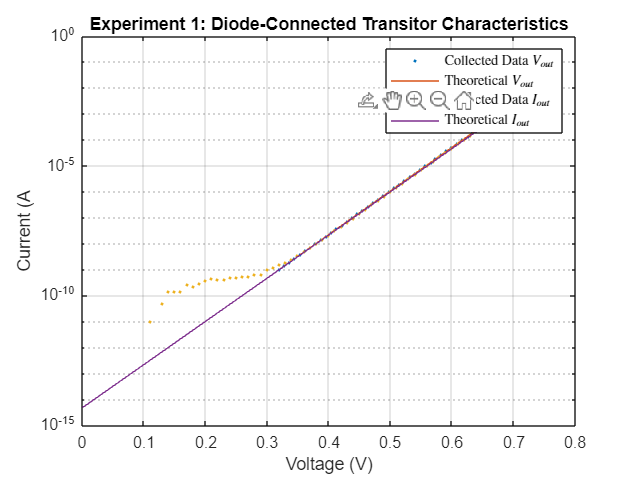


th_Iout = Is2*exp(Vin/Ut2);
th_Vout = Ut2*log((Iin)/Is2);
%plot(Iin, th_Vout)
semilogy(Vin, th_Iout)

legend("Collected Data $V_{out}$", "Theoretical $V_{out}$", "Collected Data $I_{out}$", "Theoretical $I_{out}$", "Interpreter", "latex")


hold off

%Experiment 1: 
clf

R = diff(Vout)./diff(Iin)

R = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0011    0.0017    0.0021    0.0032    0.0040    0.0062    0.0077    0.0113    0.0157    0.0205    0.0321    0.0397    0.0620    0.0766    0.1197    0.1478    0.2311    0.2854    0.4461    0.5510    0.8613    1.0638    1.6630    2.2593


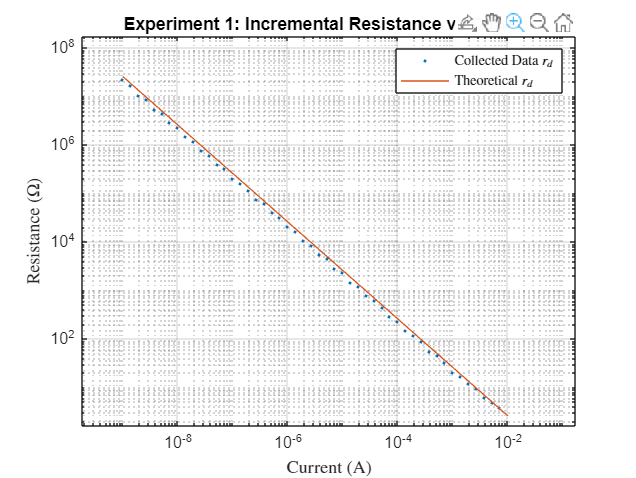

loglog(Iin(2:end), R, '.')
hold on
title("Experiment 1: Incremental Resistance vs Current")
xlabel("Current (A)", "Interpreter", "latex")
ylabel("Resistance ($\Omega$)", "Interpreter", "latex")
grid on

% line of best fit
th_R = Ut./Iin; % = dv/dI
loglog(Iin, th_R)

legend("Collected Data $r_{d}$", "Theoretical $r_{d}$", "Interpreter", "latex")

clear
clf

load('Experiment 2/100kohmnew/Vout.mat')
load('Experiment 2/100kohmnew/Vin.mat')
load('Experiment 2/100kohmnew/Iout.mat')
Vin_100k = Vin;
Vout_100k = Vout;
Iout_100k = Iout;
[first_vlow_100k, last_vlow_100k, mmax_vlow_100k, bmax_vlow_100k, Nmax_vlow_100k]=linefit(Vin_100k(1:40), Vout_100k(1:40), 5e-4)

first_vlow_100k = 1

last_vlow_100k = 39

mmax_vlow_100k = 0.9750

bmax_vlow_100k = 0.0173

Nmax_vlow_100k = 39

[first_vhigh_100k, last_vhigh_100k, mmax_vhigh_100k, bmax_vhigh_100k, Nmax_vhigh_100k]=linefit(Vin_100k(60:end), Vout_100k(60:end), 0.05)

first_vhigh_100k = 6

last_vhigh_100k = 132

mmax_vhigh_100k = 0.0359

bmax_vhigh_100k = 0.5192

Nmax_vhigh_100k = 127

[first_diode_100k, last_diode_100k, mmax_diode_100k, bmax_diode_100k, Nmax_diode_100k]=linefit(Vin_100k(20:40), log(Iout_100k(20:40)), 5e-4)

first_diode_100k = 10

last_diode_100k = 17

mmax_diode_100k = 33.8034

bmax_diode_100k = -31.4433

Nmax_diode_100k = 8

[first_resistor_100k, last_resistor_100k, mmax_resistor_100k, bmax_resistor_100k, Nmax_resistor_100k]=linefit(Vin_100k(100:end), Iout_100k(100:end), 5e-4)

first_resistor_100k = 9

last_resistor_100k = 92

mmax_resistor_100k = 9.7393e-06

bmax_resistor_100k = -5.1796e-06

Nmax_resistor_100k = 84

Ut_100k = 1/mmax_diode_100k

Ut_100k = 0.0296

Is_100k = exp(bmax_diode_100k)

Is_100k = 2.2099e-14

Ion_100k = Ut_100k / 100000

Ion_100k = 2.9583e-07

Von_100k = Ut_100k * log(Ion_100k/Is_100k)

Von_100k = 0.4854

R_100k = 1/mmax_resistor_100k;
% syms x_100k
% Vout_syms_100k(x_100k) = (x_100k * R_100k) + (Ut_100k * log(x_100k/Is_100k));
% Iout_syms_100k = finverse(Vout_syms_100k);
% Iout_theoretical_100k = subs(Iout_syms_100k, x_100k, Vin_100k);
Iout_theoretical_diode_100k = Is_100k * exp(Ut_100k./Vin_100k);
Iout_theoretical_resistor_100k = (Vin_100k * mmax_resistor_100k) + bmax_resistor_100k;
find_100k = find(Von_100k < Vin_100k);
index_100k = find_100k(1);
load('Experiment 2/10kohmnew/Vout.mat')
load('Experiment 2/10kohmnew/Vin.mat')
load('Experiment 2/10kohmnew/Iout.mat')
Vin_10k = Vin;
Vout_10k = Vout;
Iout_10k = Iin;
[first_vlow_10k, last_vlow_10k, mmax_vlow_10k, bmax_vlow_10k, Nmax_vlow_10k]=linefit(Vin_10k(1:40), Vout_10k(1:40), 5e-4)

first_vlow_10k = 1

last_vlow_10k = 34

mmax_vlow_10k = 0.9791

bmax_vlow_10k = -0.0158

Nmax_vlow_10k = 34

[first_vhigh_10k, last_vhigh_10k, mmax_vhigh_10k, bmax_vhigh_10k, Nmax_vhigh_10k]=linefit(Vin_10k(60:end), Vout_10k(60:end), 0.05)

first_vhigh_10k = 1

last_vhigh_10k = 122

mmax_vhigh_10k = 0.0374

bmax_vhigh_10k = 0.5411

Nmax_vhigh_10k = 122

[first_diode_10k, last_diode_10k, mmax_diode_10k, bmax_diode_10k, Nmax_diode_10k]=linefit(Vin_10k(10:45), log(Iout_10k(10:45)), 5e-4)

first_diode_10k = 9

last_diode_10k = 23

mmax_diode_10k = 36.5429

bmax_diode_10k = -32.4920

Nmax_diode_10k = 15

[first_resistor_10k, last_resistor_10k, mmax_resistor_10k, bmax_resistor_10k, Nmax_resistor_10k]=linefit(Vin_10k(100:end), Iout_10k(100:end), 5e-4)

first_resistor_10k = 14

last_resistor_10k = 82

mmax_resistor_10k = 9.7207e-05

bmax_resistor_10k = -5.7550e-05

Nmax_resistor_10k = 69

Ut_10k = 1/mmax_diode_10k

Ut_10k = 0.0274

Is_10k = exp(bmax_diode_10k)

Is_10k = 7.7428e-15

Ion_10k = Ut_10k / 10000

Ion_10k = 2.7365e-06

Von_10k = Ut_10k * log(Ion_10k/Is_10k)

Von_10k = 0.5386

R_10k = 1/mmax_resistor_10k;
Iout_theoretical_diode_10k = Is_10k * exp(Ut_10k./Vin_10k);
Iout_theoretical_resistor_10k = (Vin_10k * mmax_resistor_10k) + bmax_resistor_10k;
find_10k = find(Von_10k < Vin_10k);
index_10k = find_10k(1);
load('Experiment 2/1kohmnew/Vout.mat')
load('Experiment 2/1kohmnew/Vin.mat')
load('Experiment 2/1kohmnew/Iout.mat')
Vin_1k = Vin;
Vout_1k = Vout;
Iout_1k = Iin;
[first_vlow_1k, last_vlow_1k, mmax_vlow_1k, bmax_vlow_1k, Nmax_vlow_1k]=linefit(Vin_1k(1:40), Vout_1k(1:40), 5e-4)

first_vlow_1k = 4

last_vlow_1k = 40

mmax_vlow_1k = 0.9792

bmax_vlow_1k = -0.0329

Nmax_vlow_1k = 37

[first_vhigh_1k, last_vhigh_1k, mmax_vhigh_1k, bmax_vhigh_1k, Nmax_vhigh_1k]=linefit(Vin_1k(60:end), Vout_1k(60:end), 0.05)

first_vhigh_1k = 1

last_vhigh_1k = 7

mmax_vhigh_1k = 0.1139

bmax_vhigh_1k = 0.5063

Nmax_vhigh_1k = 7

[first_diode_1k, last_diode_1k, mmax_diode_1k, bmax_diode_1k, Nmax_diode_1k]=linefit(Vin_1k(10:100), log(Iout_1k(10:100)), 5e-4)

first_diode_1k = 12

last_diode_1k = 29

mmax_diode_1k = 37.4647

bmax_diode_1k = -32.8285

Nmax_diode_1k = 18

[first_resistor_1k, last_resistor_1k, mmax_resistor_1k, bmax_resistor_1k, Nmax_resistor_1k]=linefit(Vin_1k(100:end), Iout_1k(100:end), 5e-4)

first_resistor_1k = 13

last_resistor_1k = 82

mmax_resistor_1k = 9.6661e-04

bmax_resistor_1k = -6.2660e-04

Nmax_resistor_1k = 70

Ut_1k = 1/mmax_diode_1k

Ut_1k = 0.0267

Is_1k = exp(bmax_diode_1k)

Is_1k = 5.5306e-15

Ion_1k = Ut_1k / 1000

Ion_1k = 2.6692e-05

Von_1k = Ut_1k * log(Ion_1k/Is_1k)

Von_1k = 0.5952

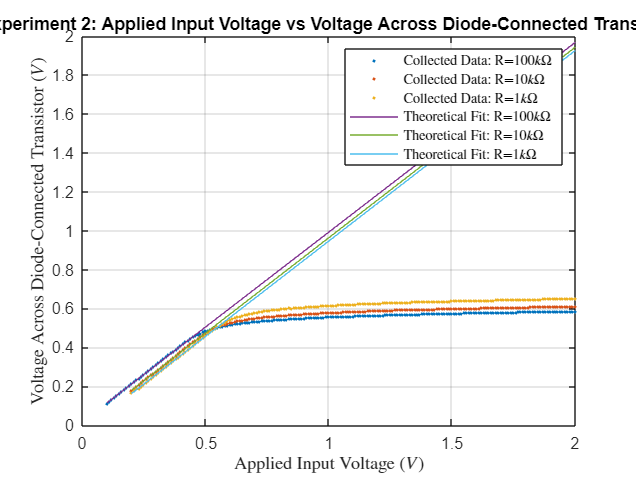

R_1k = 1/mmax_resistor_1k;
Iout_theoretical_diode_1k = Is_1k * exp(Ut_100k./Vin_1k);
Iout_theoretical_resistor_1k = (Vin_1k * mmax_resistor_1k) + bmax_resistor_1k;
find_1k = find(Von_1k < Vin_1k);

index_1k = find_1k(1);
plot(Vin_100k, Vout_100k, '.');
hold on;
grid on;
plot(Vin_10k, Vout_10k, '.');
plot(Vin_1k, Vout_1k, '.');
plot(Vin_100k, (Vin_100k*mmax_vlow_100k) + bmax_vlow_100k);
plot(Vin_10k, (Vin_10k*mmax_vlow_10k) + bmax_vlow_10k);
plot(Vin_1k, (Vin_1k*mmax_vlow_1k) + bmax_vlow_1k);
legend("Collected Data: R=$100k\Omega$", "Collected Data: R=$10k\Omega$", "Collected Data: R=$1k\Omega$", "Theoretical Fit: R=$100k\Omega$", "Theoretical Fit: R=$10k\Omega$", "Theoretical Fit: R=$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Voltage Across Diode-Connected Transistor")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Voltage Across Diode-Connected Transistor ($V$)", "Interpreter", "latex")
hold off;

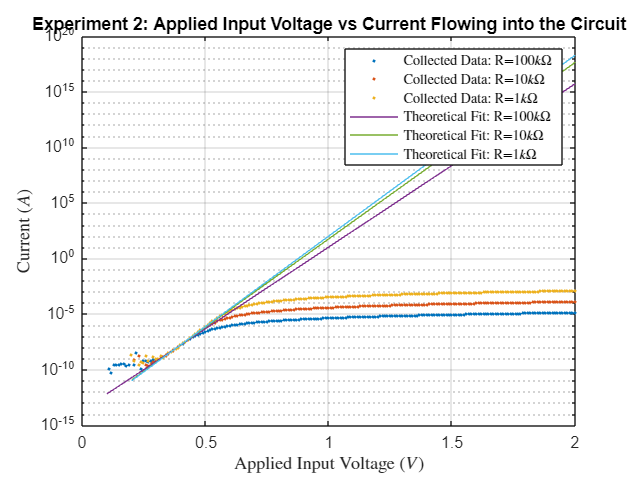


semilogy(Vin_100k, Iout_100k, '.');
hold on;
grid on;
semilogy(Vin_10k, Iout_10k, '.');
semilogy(Vin_1k, Iout_1k, '.');

semilogy(Vin_100k, exp(bmax_diode_100k)*exp(Vin_100k/(1/mmax_diode_100k)));
semilogy(Vin_10k, exp(bmax_diode_10k)*exp(Vin_10k/(1/mmax_diode_10k)));
semilogy(Vin_1k, exp(bmax_diode_1k)*exp(Vin_1k/(1/mmax_diode_1k)));

legend("Collected Data: R=$100k\Omega$", "Collected Data: R=$10k\Omega$", "Collected Data: R=$1k\Omega$", "Theoretical Fit: R=$100k\Omega$", "Theoretical Fit: R=$10k\Omega$", "Theoretical Fit: R=$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")
hold off;



plot(Vin_100k, Iout_100k, '.');

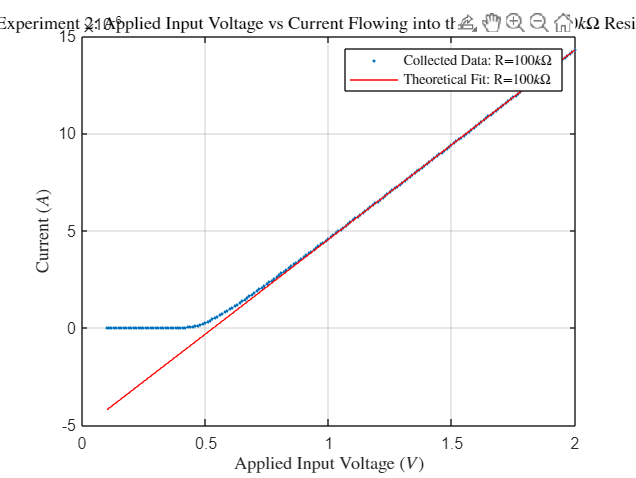

hold on;
grid on
plot(Vin_100k, Iout_theoretical_resistor_100k, "-r");
legend("Collected Data: R=$100k\Omega$", "Theoretical Fit: R=$100k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit for $100k\Omega$ Resistor", "Interpreter","latex")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")
hold off;

plot(Vin_10k, Iout_10k, '.');

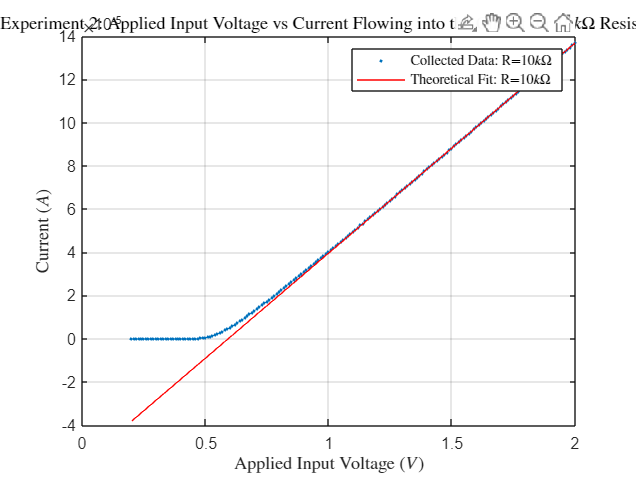

hold on;
grid on
plot(Vin_10k, Iout_theoretical_resistor_10k, "-r");
legend("Collected Data: R=$10k\Omega$", "Theoretical Fit: R=$10k\Omega$",  "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit for $10k\Omega$ Resistor", "Interpreter","latex")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")

hold off;

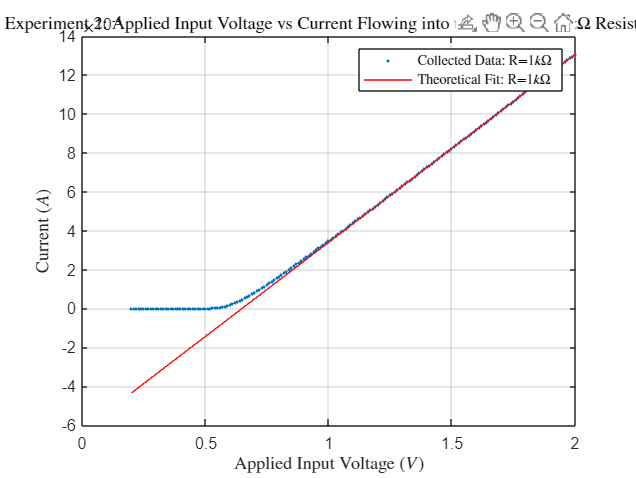

plot(Vin_1k, Iout_1k, '.');
hold on;
grid on
plot(Vin_1k, Iout_theoretical_resistor_1k, "-r");
plot(Von_1k,Iout_theoretical_resistor_1k,"-k")
legend("Collected Data: R=$1k\Omega$", "Theoretical Fit: R=$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit for $1k\Omega$ Resistor", "Interpreter","latex")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")

hold off;

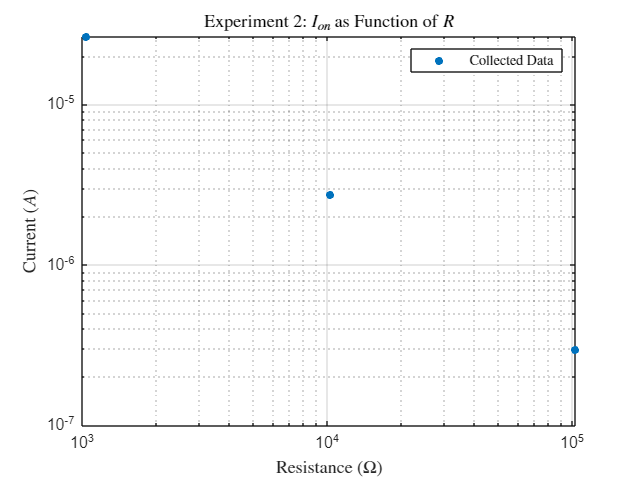


loglog([R_1k, R_10k, R_100k], [Ion_1k, Ion_10k, Ion_100k], '.','MarkerSize',15);
hold on
grid on
legend("Collected Data", "Interpreter","latex")
title("Experiment 2: $I_{on}$ as Function of $R$", "Interpreter","latex")
xlabel("Resistance ($\Omega$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")
hold off

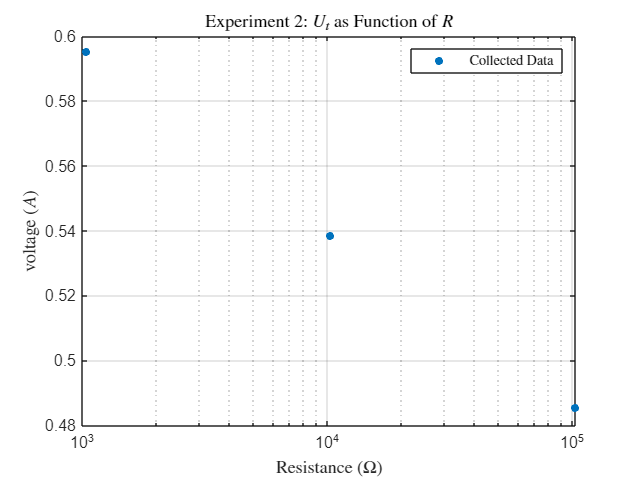



semilogx([R_1k, R_10k, R_100k], [Von_1k, Von_10k, Von_100k], '.','MarkerSize',15);
hold on
grid on
legend("Collected Data", "Interpreter","latex")
title("Experiment 2: $U_{t}$ as Function of $R$", "Interpreter","latex")
xlabel("Resistance ($\Omega$)", "Interpreter", "latex")
ylabel("voltage ($A$)", "Interpreter", "latex")
hold off